# Two Sine Phase

t = (0:0.001:1)';

phase1 = deg2rad(0.0);
phase2 = deg2rad(85);
phase3 = deg2rad(95);

sine1 = 1*sin(2*pi*5*t + phase1) + randn(size(t))*0.2;
sine2 = 2*sin(2*pi*5*t + phase2)+ randn(size(t))*0.4;
sine3 = 3*sin(2*pi*5*t + phase3) + randn(size(t))*0.6;

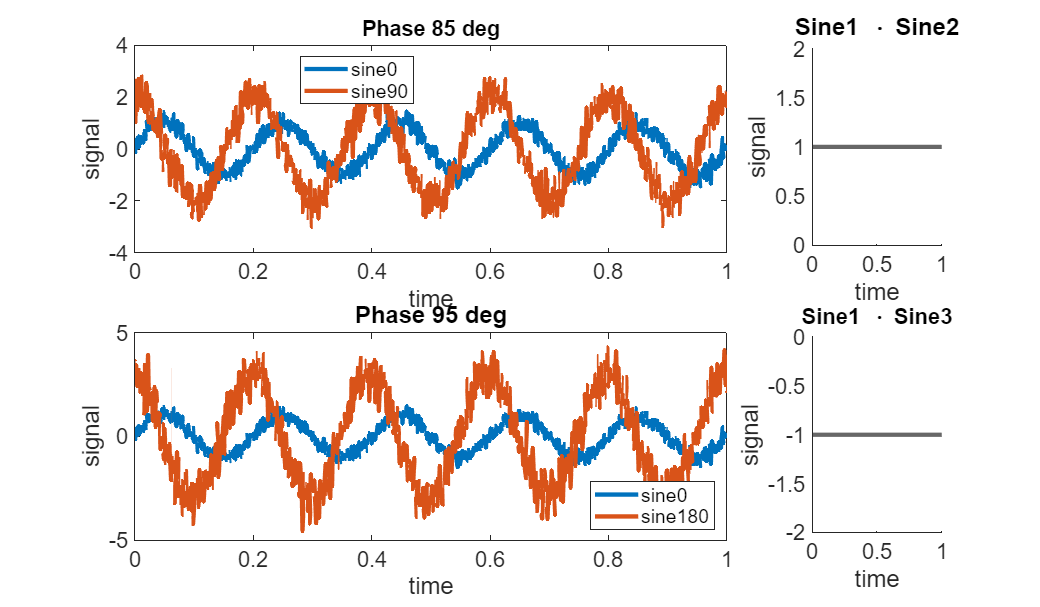

figure('Position',[0 0 1200 700])

subplot(2,4,1:3)
plot(t, sine1, 'LineWidth',3, 'DisplayName','sine0'), hold on,...
plot(t, sine2, 'LineWidth',3, 'DisplayName','sine90'), legend('show', 'Location', 'best', 'ItemHitFcn', @clickLegendToHide)
set(gca, 'FontSize', 15)
title(sprintf('Phase %d deg', rad2deg(phase2)), 'FontSize',15)
xlabel('time')
ylabel('signal')

subplot(2,4,4)

yline(sign(dot(sine1, sine2)), 'LineWidth',3)
title('Sine1 \cdot Sine2', 'FontSize',15)
set(gca, 'FontSize', 15)

xlabel('time')
ylabel('signal')

subplot(2,4,5:7)
plot(t, sine1, 'LineWidth',3, 'DisplayName','sine0'), hold on,...
plot(t, sine3, 'LineWidth',3, 'DisplayName','sine180'), legend('show', 'Location', 'best', 'ItemHitFcn', @clickLegendToHide)
title(sprintf('Phase %d deg', rad2deg(phase3)), 'FontSize',15)
set(gca, 'FontSize', 15)
xlabel('time')
ylabel('signal')

subplot(2,4,8)
yline(sign(dot(sine1, sine3)), 'LineWidth',3)
set(gca, 'FontSize', 15)
title('Sine1 \cdot Sine3', 'FontSize',15)
xlabel('time')
ylabel('signal')